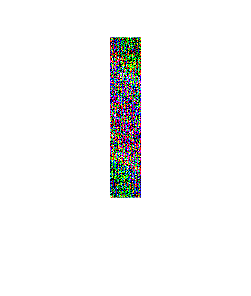

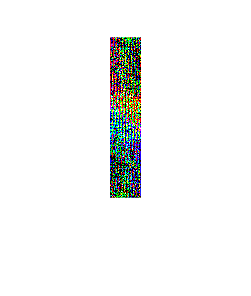

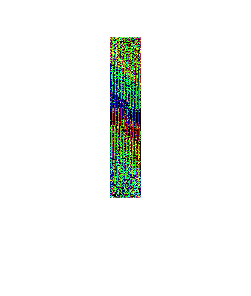

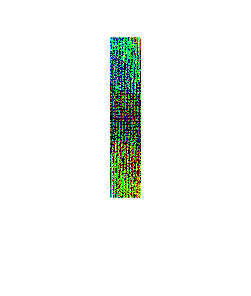

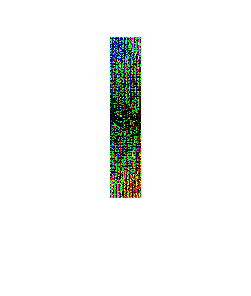

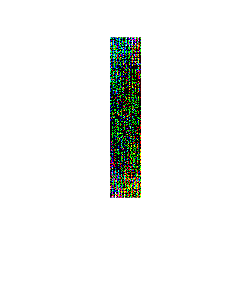

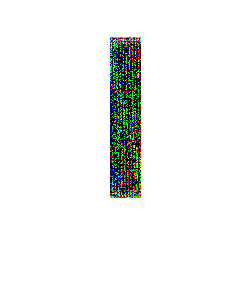

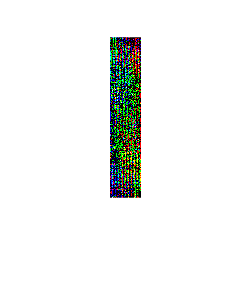

for i = 1:n_discrete(1)
p = reshape(a6_mat(i,1:3,:,:),[n_discrete(3:4),3]);
figure
imshow(p)
end

ltr_planner = ExplicitLTR_TrajPlanner('a6_mat',a6_mat,'b6_mat',b6_mat, ...
    'v0_seq',v0_seq,'x_seq',x_seq,'y_seq',y_seq,'Dth_seq',Dth_seq,'tf',tf)

ltr_planner =   ExplicitLTR_TrajPlanner - 属性:

        a6_mat: [6×20×31×21 double]
        b6_mat: [6×20×31×21 double]
            tf: 4
         range: [4×2 double]
        v0_seq: [15 16 17 18 19 20]
         x_seq: [60 61.0526 62.1053 63.1579 64.2105 65.2632 66.3158 67.3684 68.4211 69.4737 70.5263 71.5789 72.6316 73.6842 74.7368 75.7895 76.8421 77.8947 78.9474 80]
         y_seq: [-15 -13.8081 -12.6332 -11.4762 -10.3384 -9.2211 -8.1259 -7.0549 -6.0103 -4.9953 -4.0137 -3.0708 -2.1743 -1.3367 -0.5818 0 0.5818 1.3367 2.1743 3.0708 4.0137 4.9953 6.0103 7.0549 8.1259 9.2211 10.3384 11.4762 12.6332 13.8081 15]
       Dth_seq: [-0.2618 -0.2307 -0.2003 -0.1706 -0.1418 -0.1140 -0.0872 -0.0617 -0.0379 -0.0165 0 0.0165 0.0379 0.0617 0.0872 0.1140 0.1418 0.1706 0.2003 0.2307 0.2618]
    resolution: 0.1000


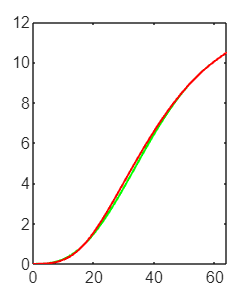

figureID = 5;
v0 = 16;
x = v0*tf;
y = 10.5;
Dth = 6/180*pi;
ltr_planner.plotLTRminTraj(v0,x,y,Dth,figureID)

% axis equal
ltr_planner.getProximatedSpd(v0,x,y,Dth)

ans = 17.3447